We test first-order and second-order differentiation matrices for the function $x + e^{\sin 4x}$ over $[-1,1]$. 

f = @(x) x + exp(sin(4*x));

For reference, here are the exact first and second derivatives.

dfdx = @(x) 1 + 4*exp(sin(4*x)).*cos(4*x);
d2fdx2 = @(x) 4*exp(sin(4*x)).*(4*cos(4*x).^2-4*sin(4*x));

We discretize on equally spaced nodes and evaluate $f$ at the nodes. 

[t,Dx,Dxx] = diffmat2(12,[-1 1]);
y = f(t);

Then the first two derivatives of $f$ each require one matrix-vector multiplication.

yx = Dx*y;
yxx = Dxx*y;

The results are fair but not very accurate for this small value of $n$. 

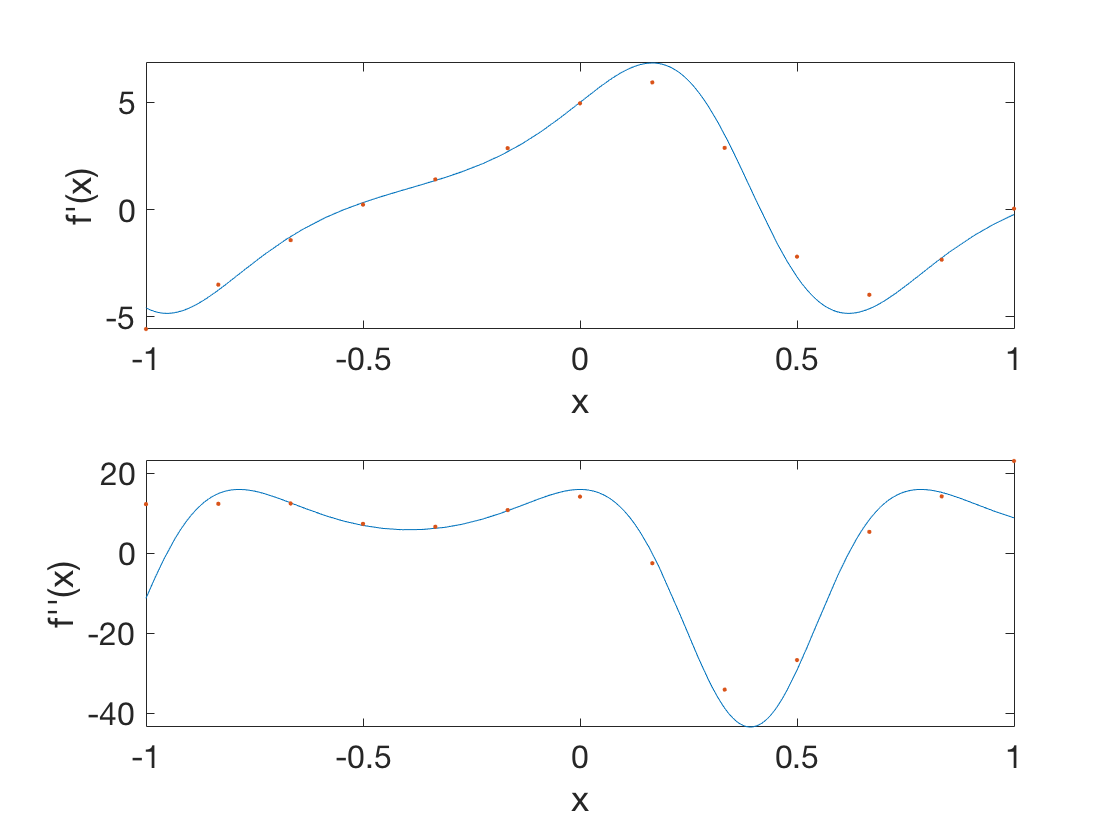

subplot(2,1,1)
fplot(dfdx,[-1 1]), hold on
plot(t,yx,'.')
xlabel('x'), ylabel('f''(x)')   % ignore this line
subplot(2,1,2)
fplot(d2fdx2,[-1 1]), hold on
plot(t,yxx,'.')
xlabel('x'), ylabel('f''''(x)')   % ignore this line

An experiment confirms the order of accuracy.

n = round( 2.^(4:.5:11)' );
err1 = 0*n;
err2 = 0*n;

for k = 1:length(n)
    [t,Dx,Dxx] = diffmat2(n(k),[-1 1]);
    y = f(t);
    err1(k) = norm( dfdx(t) - Dx*y, inf );
    err2(k) = norm( d2fdx2(t) - Dxx*y, inf );
end

For $O(n^{-p})$ convergence, we use a log-log plot of the errors. 

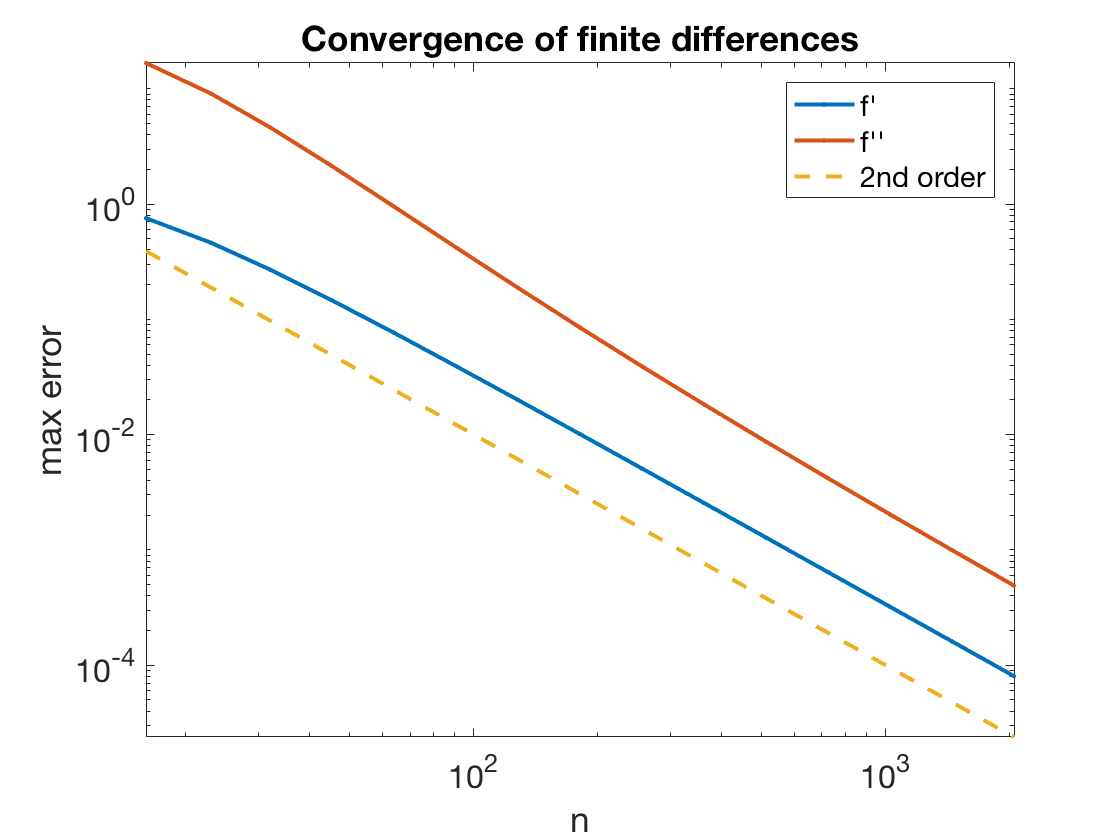

clf    % ignore this line
loglog(n,[err1,err2],'.-'), hold on
loglog(n,10*10*n.^(-2),'--')
axis tight, legend('f''','f''''','2nd order')   % ignore this line
xlabel('n'), ylabel('max error')   % ignore this line
title('Convergence of finite differences')   % ignore this line